[signal, Fs] = audioread("audio_piano.m4a");

sound(signal, Fs);

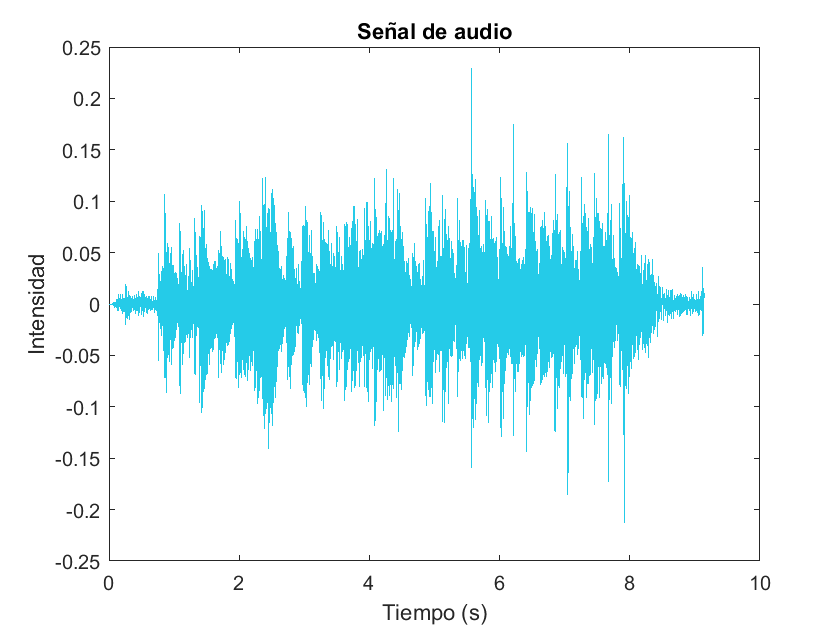

deltaT = 1/Fs;
tArray = (0:length(signal)-1)*deltaT;

figure()
plot(tArray, signal, "Color", "#25cbe8");
title("Señal de audio")
xlabel("Tiempo (s)")
ylabel("Intensidad")

Lo que quisiera realmente filtrar aquí son los golpes al tocar las teclas si es posible, 

### CWT

Aquí decidí usar la función que ya trae disponible MATLAB, ya que la mía es demasiado ineficiente con señales muy grandes. 

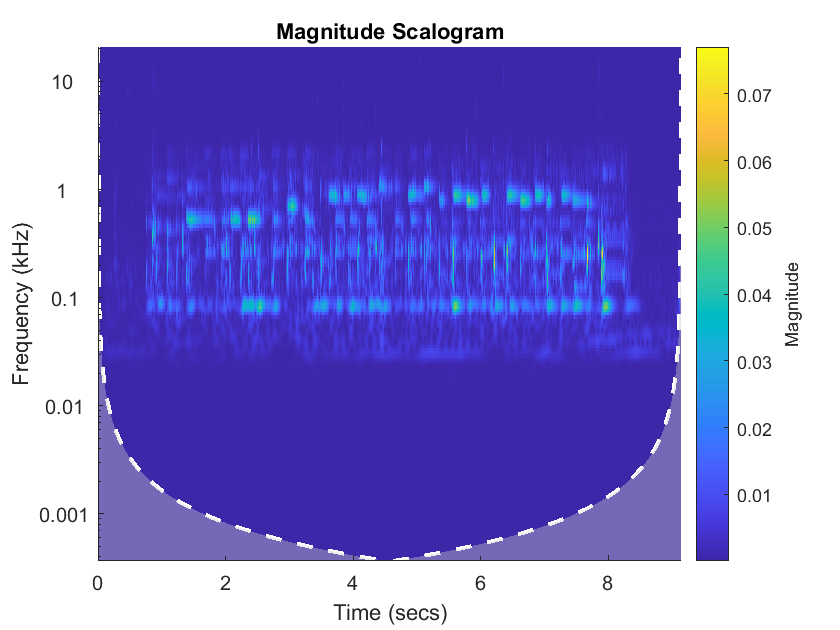

cwt(signal, Fs)

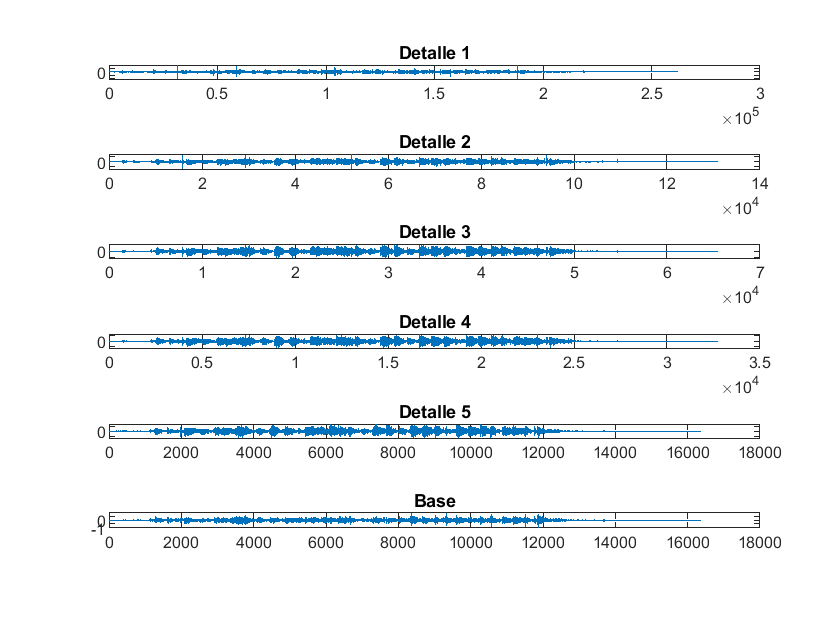

discreteCalculator = DiscreteWaveletTransform();

[details, base] = discreteCalculator.computeDWT(WaveletType.DAUBECHIES_1, signal, 5);

figure()
for i = 1:length(details)
    subplot(length(details) + 1,1,i)
    plot(details{i})
    title("Detalle "+string(i))
end

subplot(length(details) + 1,1,length(details) + 1)
plot(base)
title("Base")

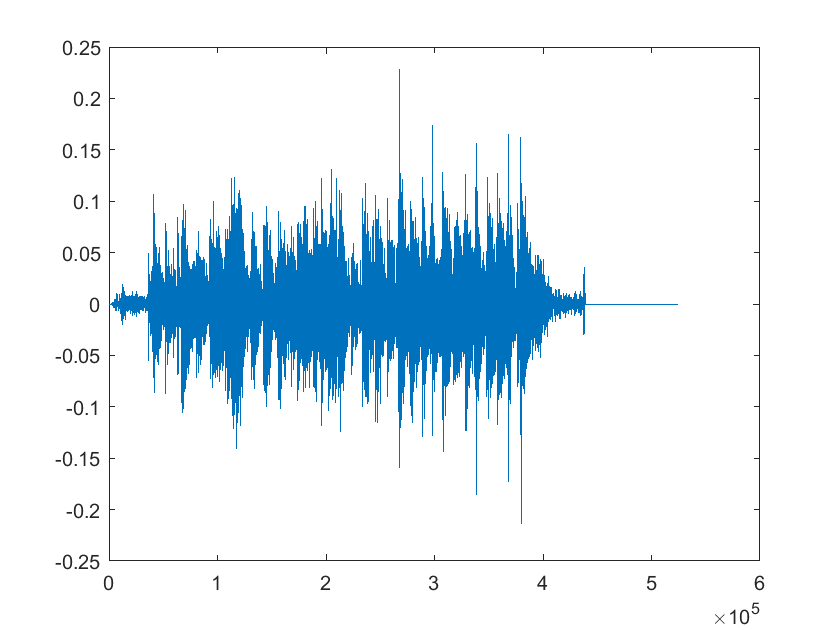

filteredDetails = details;
base2 = base;
%filteredDetails{1} = filteredDetails{1}*0.5;
%filteredDetails{2} = filteredDetails{2}*0.5;
%filteredDetails{3} = filteredDetails{3}*0;
%filteredDetails{4} = filteredDetails{4}*0
%filteredDetails{5} = filteredDetails{5}*0;
%filteredDetails{9} = filteredDetails{9}*0;

%base2 = base2*0;
reconstructedSignal = discreteCalculator.reconstructDWT(WaveletType.DAUBECHIES_1, filteredDetails, base2);

figure()
title("Señal reconstruida")
plot(reconstructedSignal);

sound(reconstructedSignal, Fs)

### Daubechies 4 (con librerias de MATLAB)

discreteCalculator = DiscreteWaveletTransform();

[details, base] = discreteCalculator.computeDWTNoSampling(WaveletType.DAUBECHIES_4, signal,5);

Unrecognized function or variable 'signal'.


figure()
for i = 1:length(details)
    subplot(length(details) + 1,1,i)
    plot(details{i})
    title("Detalle "+string(i))
end

subplot(length(details) + 1,1,length(details) + 1)
plot(base)
title("Base")

sound(details{1}*50,Fs);

sound(base, Fs);

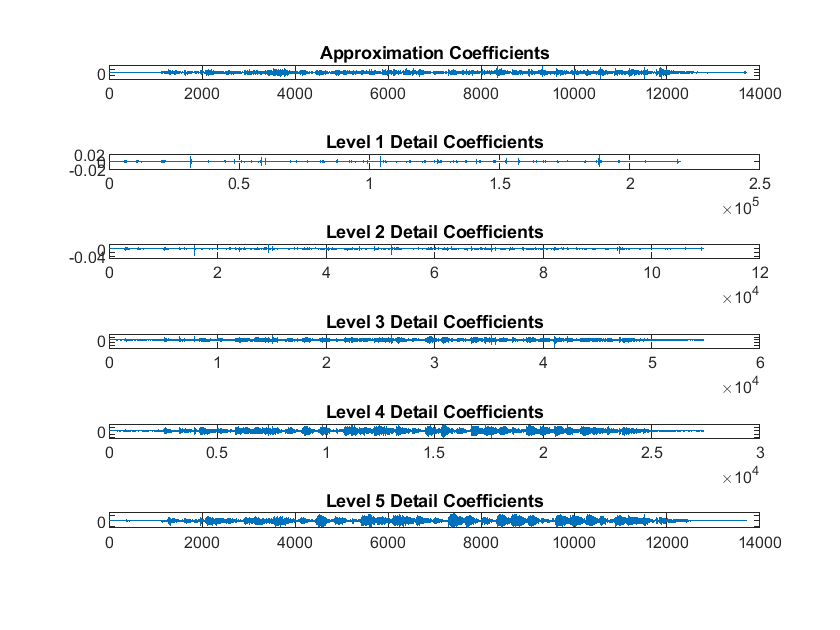

[c,l] = wavedec(signal,5,'db2');
approx = appcoef(c,l,'db2');
[cd1 cd2 cd3 cd4 cd5] = detcoef(c,l,[1 2 3 4 5]);
%Plot the coefficients.
figure()
subplot(6,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(6,1,2)
plot(cd1)
title('Level 1 Detail Coefficients')
subplot(6,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(6,1,4)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(6,1,5)
plot(cd4)
title('Level 4 Detail Coefficients')
subplot(6,1,6)
plot(cd5)
title('Level 5 Detail Coefficients')

[c,l] = wavedec(signal,5,'db2');
approx = appcoef(c,l,'db2');
[cd1 cd2 cd3 cd4 cd5] = detcoef(c,l,[1 2 3 4 5]);

%Quitemos el primer detalle
c(l(5):l(6)) = 0;
c(l(6):l(7)) = 0;

reconstructedSignal = waverec(c,l,'db2');

sound(reconstructedSignal, Fs)